This Live Script file will be presented to your end user in the Live Editor just as you see it here.  You can take advantage of all of the features of Live Script to present information and examples.

# Getting Started with Simple Log Toolbox

## Description

**Simple Log Toolbox** is a comprehensive and flexible logging system for MATLAB applications that provides structured logging with multiple severity levels, real-time UI monitoring, and event-driven architecture.

## System Requirements

The toolbox has been developed under R2025a.

## Features

- **Hierarchical log levels**: Debug, Information, Warning, and Error levels with automatic filtering

- **Flexible message formatting**: sprintf-style formatting with metadata support

- **Real-time UI viewer**: Live log monitoring with filtering and search capabilities

- **Event-driven architecture**: Subscribe to log events for custom processing

- **Singleton pattern**: Global logger access with support for multiple independent loggers

- **File export**: Save log messages to files with consistent formatting

- **Console output control**: Enable/disable console output as needed

- **Source tracking**: Identify message origins for better debugging

- **Completely customizable**: Create your own logger providing a custom message formatting or sending logs to external services

- **Customizable UI**: Abstract log monitor UI component ready to be customized

## Basic usage

Let's start with some simple logging examples:

### Simple logging

log.info('Application started');

|              | 19-Jul-2025 14:07:22 | Information | Application started


log.warn('Configuration file not found, using defaults');

|              | 19-Jul-2025 14:07:22 | Warning     | Configuration file not found, using defaults


log.error('Failed to connect to database', ThrowError=false);

|              | 19-Jul-2025 14:07:22 | Error       | Failed to connect to database


### Formatted messages with variables

itemCount = 42;
username = 'JohnDoe';
ipAddress = '192.168.1.100';

log.info('Processing %d items', itemCount);

|              | 19-Jul-2025 14:07:23 | Information | Processing 42 items


log.debug('User %s logged in from %s', username, ipAddress);


### Understanding log levels

The toolbox provides four hierarchical log levels:

- **Debug (0)**: Detailed debugging information (step-by-step execution, variable dumps, detailed diagnostics)

- **Information (1)**: General informational messages (normal operation confirmations, progress updates)

- **Warning (2)**: Warning messages for non-critical issues (recoverable errors, deprecated features, configuration issues)

- **Error (3)**: Error messages for critical problems (critical failures, validation errors, unrecoverable problems)

Let's demonstrate each level:

log.debug('This is a debug message - very detailed information');
log.info('This is an info message - general operation status');

|              | 19-Jul-2025 14:07:25 | Information | This is an info message - general operation status


log.warn('This is a warning - something to pay attention to');

|              | 19-Jul-2025 14:07:25 | Warning     | This is a warning - something to pay attention to


log.error('This is an error - something went wrong', 'ThrowError', false);

|              | 19-Jul-2025 14:07:25 | Error       | This is an error - something went wrong


### Live log viewer

The toolbox includes a real-time UI viewer for monitoring logs.

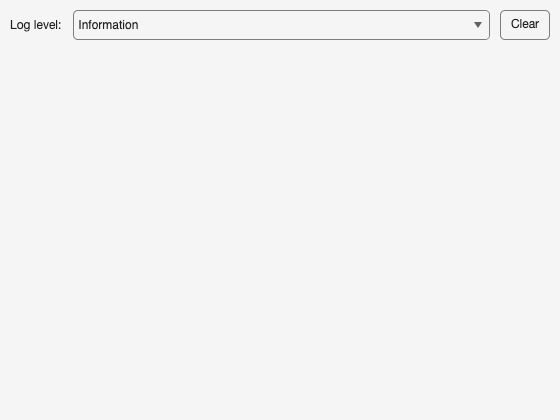

viewer = log.ui();

The viewer will show all subsequent log messages in real-time.

### Configuring the logger

Get the current logger and configure its behavior:

logger = log.logger.Current

logger =   logger with properties:

            Level: Information
    ConsoleOutput: 1
        NotifyAll: 1


Let's change the log level to see how filtering works:

% Set to Debug level (shows all messages)
logger.Level = log.level.Debug;
fprintf('\nSet to Debug level - all messages will be shown:\n');


Set to Debug level - all messages will be shown:



log.debug('Debug message - now visible');

|              | 19-Jul-2025 14:07:37 | Debug       | Debug message - now visible


log.info('Info message');

|              | 19-Jul-2025 14:07:37 | Information | Info message


log.warn('Warning message');

|              | 19-Jul-2025 14:07:37 | Warning     | Warning message



% Now set to Warning level (shows only warnings and errors):
logger.Level = log.level.Warning;
fprintf('\nSet to Warning level - only warnings and errors shown:\n');


Set to Warning level - only warnings and errors shown:



log.debug('Debug message - filtered out');
log.info('Info message - filtered out');  
log.warn('Warning message - visible');

|              | 19-Jul-2025 14:07:37 | Warning     | Warning message - visible


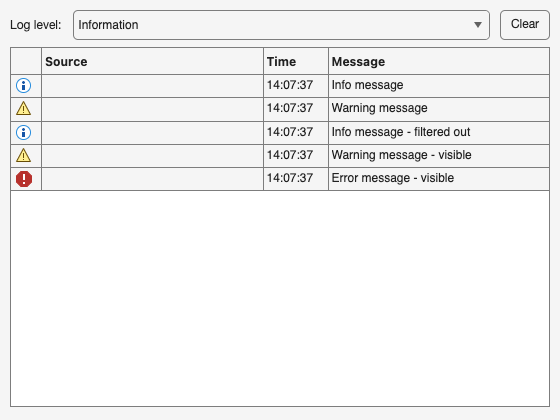

|              | 19-Jul-2025 14:07:37 | Error       | Error message - visible


log.error('Error message - visible', 'ThrowError', false);


% Reset to Information level for the rest of the demo:
logger.Level = log.level.Information;

## Advanced usage

### Working with messages directly

You can create and work with message objects directly:

| DataProcessor | 19-Jul-2025 14:07:41 | Information | Operation completed


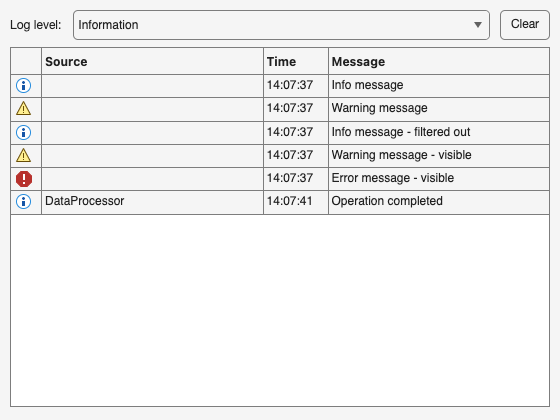

% Create message with metadata
msg1 = log.message("Operation completed", ...
    Source="DataProcessor", ...
    Level="Information");

% Create multiple messages
msg2 = log.message("Processing started", Level="Information");
msg3 = log.message("Low memory warning", Level="Warning");
msg4 = log.message("Processing completed", Level="Information");

% Send individual message to logger
msg1.log();


fprintf('Created %d message objects\n', 4);

Created 4 message objects


### Source identification

Use source identification for better traceability:

log.info('User authenticated', Source='AuthModule');

| AuthModule   | 19-Jul-2025 14:07:46 | Information | User authenticated


log.warn('Connection timeout, retrying...', Source='NetworkManager'); 

| NetworkManager | 19-Jul-2025 14:07:46 | Warning     | Connection timeout, retrying...


log.info('Database query executed', Source='DatabaseManager');

| DatabaseManager | 19-Jul-2025 14:07:46 | Information | Database query executed


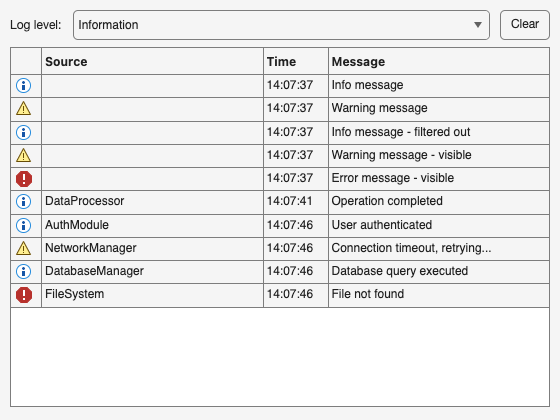

| FileSystem   | 19-Jul-2025 14:07:46 | Error       | File not found


log.error('File not found', Source='FileSystem', ThrowError=false);

### Assertions with logging

The toolbox provides assertion capabilities with automatic logging:

% Test with valid condition
x = 10;
log.assert(x > 0, 'Value must be positive');
fprintf('Assertion passed: x = %d > 0\n', x);

Assertion passed: x = 10 > 0


|              | 19-Jul-2025 14:08:28 | Error       | Value must be positive


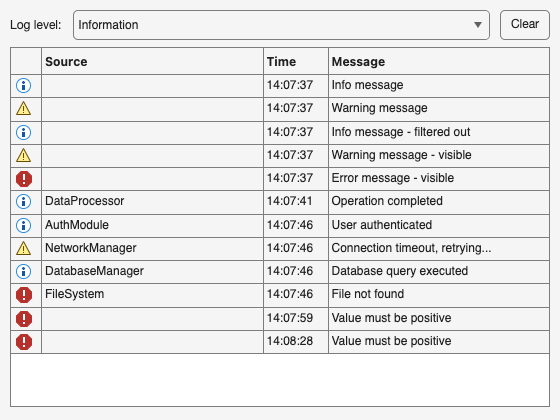


% Test with invalid condition (but don't throw error):
y = -5;
log.assert(y > 0, 'Value must be positive', ThrowError=false);

fprintf('Assertion failed: y = %d\n', y);

Assertion failed: y = -5


### File export

Save log messages to files:

% Create an array of messages
messages = [
    log.message("Process started", Level="Information");
    log.message("Warning: Low memory", Level="Warning");
    log.message("Process completed", Level="Information");
];

% Save to file (uncomment to actually save)
% messages.save('process_log.txt');
fprintf('Created %d messages ready for export\n', length(messages));

Created 3 messages ready for export


### Event-driven architecture

You can listen to log events for custom processing:

% Example event handler function
function handleLogEvent(~, eventData)
    msg = eventData.Message;
    if msg.Level == log.level.Error
        fprintf('[EVENT] Error detected: %s\n', msg.Message);
    end
end



=== Development Configuration ===


% Add event listener (uncomment to activate)
listener = addlistener(logger, 'MessageReceived', @handleLogEvent);


Event listeners can be attached to process log messages automatically.

### Development vs production configuration

% Verbose logging for development
fprintf('\n=== Development Configuration ===\n');

|              | 19-Jul-2025 14:08:46 | Debug       | Development mode: verbose logging enabled


dev_logger = log.logger.Current;

|              | 19-Jul-2025 14:08:46 | Information | All message types are visible in development


dev_logger.Level = log.level.Debug;
dev_logger.ConsoleOutput = true;



=== Production Configuration ===


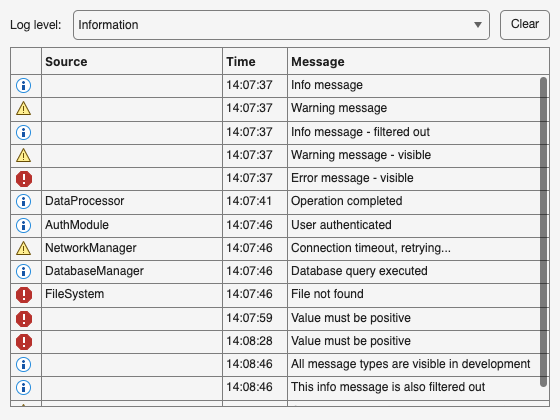

log.debug('Development mode: verbose logging enabled');
log.info('All message types are visible in development');

% Minimal logging for production  
fprintf('\n=== Production Configuration ===\n');
prod_logger = log.logger.Current;
prod_logger.Level = log.level.Warning;

prod_logger.ConsoleOutput = false;

log.debug('This debug message is filtered out in production');
log.info('This info message is also filtered out');
log.warn('Only warnings and errors appear in production');

Unrecognized function or variable 'clientIP'.

## Best practices

#### Message formatting

% Good: Descriptive messages with context
log.info('User %s successfully logged in from %s', username, clientIP);

% Good: Include relevant data
log.warn('Memory usage at %d%% of available %d MB', percentage, totalMB);

% Avoid: Vague messages
log.info('Something happened');

#### Source identification

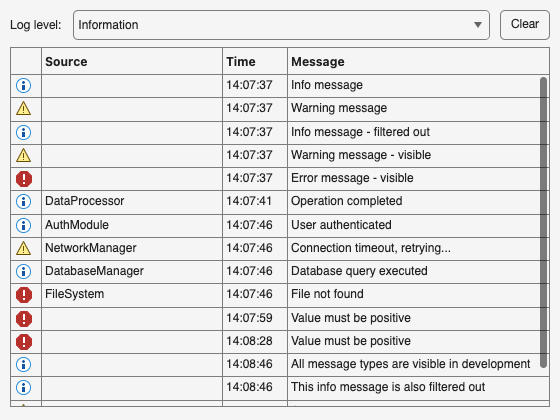

% Use consistent source names

log.info('Connection established', Source='DatabaseManager');

Unrecognized function or variable 'DatabaseManager'.

log.error('Query failed', Source='DatabaseManager');

% Group related functionality
log.debug('Parsing configuration file', Source='ConfigLoader');
log.warn('Invalid setting ignored', Source='ConfigLoader');

## Integration with existing code

#### Gradual migration

% Replace existing fprintf statements
% Old:
fprintf('Processing item %d of %d\n', i, total);

Unrecognized function or variable 'total'.


% New:
log.info('Processing item %d of %d', i, total);

#### Wrapper functions

function loggedFunction()
	log.info('Starting loggedFunction', 'Source', 'MyModule');
	try
		% Function implementation
		result = complexOperation();
		log.info('Operation completed successfully', 'Source', 'MyModule');

Current level: Debug


	catch err

Console output: true


		log.error('Operation failed: %s', err.message, 'Source', 'MyModule');
		rethrow(err);
	end
end

## Troubleshooting

### Common issues

- **Messages not appearing**: Check logger level setting

- **Too many messages**: Increase log level to reduce verbosity

- **UI not updating**: Ensure logger instance matches viewer logger

- **Performance issues**: Avoid expensive operations in debug messages

### Debug mode

% Enable maximum verbosity
logger = log.logger.Current;
logger.Level = log.level.Debug;
logger.ConsoleOutput = true;

% Check current configuration
fprintf('Current level: %s\n', logger.Level);
fprintf('Console output: %s\n', mat2str(logger.ConsoleOutput));

## License

This project is licensed under the BSD 3-Clause License - see the [LICENSE](https://127.0.0.1:31516/ui/webgui/src/LICENSE) file for details.